A = [0, 2, 0, 0;
    -2, 0, 0 ,0;
    0, 0, 0, 4;
    0, 0, -4, 0];

C = [0, 3, 2, 0];
B = [1;1;1;1];

x0 = [1; 2; 3; 4];
x1 = [0; 8; 1; 6];

warning off;
cvx_begin sdp
variable Q(4,4)
variable Y(4,1)
a = 0.1

a = 0.1000

Q > 0.0001*eye(4);
A'*Q+ Q*A + 2*a*Q +C'*Y' +Y*C <= 0;

variable Q1(4,4)
variable Y1(4,1)
a1 = 1

a1 = 1

Q1 > 0.0001*eye(4);
A'*Q1+ Q1*A + 2*a1*Q1 +C'*Y1' +Y1*C <= 0;

variable Q2(4,4)
variable Y2(4,1)
a2 = 5

a2 = 5

Q2 > 0.0001*eye(4);
A'*Q2+ Q2*A + 2*a2*Q2 +C'*Y2' +Y2*C <= 0;
cvx_end

 
Calling SDPT3 4.0: 60 variables, 18 equality constraints
------------------------------------------------------------

 num. of constraints = 18
 dim. of sdp    var  = 24,   num. of sdp  blk  =  6
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.3e+02|5.7e+01|2.7e+03| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.881|0.724|2.7e+01|1.6e+01|7.0e+02| 0.000000e+00  6.558884e-03| 0:0:00| chol  1  1 
 2|0.833|0.748|4.6e+00|4.0e+00|2.1e+02| 0.000000e+00  1.046082e-02| 0:0:00| chol  1  1 
 3|0.960|0.894|1.8e-01|4.2e-01|2.1e+01| 0.000000e+00  8.337449e-03| 0:0:00| chol  1  1 
 4|1.000|0.903|7.6e-05|4.1e-02|2.1e+00


L = inv(Q)*Y

L =     0.0185
   -0.4258
   -0.4213
   -0.3154


M = A + L*C;
Me = eig(M)

Me =   -0.5696 + 2.0295i
  -0.5696 - 2.0295i
  -0.4903 + 4.1028i
  -0.4903 - 4.1028i



L1 = inv(Q1)*Y1

L1 =     1.0024
   -4.1767
    1.5509
   -4.7470


M1 = A + L1*C;
Me1 = eig(M1)

Me1 =   -2.5713 + 5.0667i
  -2.5713 - 5.0667i
  -2.1428 + 2.2533i
  -2.1428 - 2.2533i



L2 = inv(Q2)*Y2

L2 =   323.2756
 -231.2626
  323.1342
  118.5475


M2 = A + L2*C;
Me2 = eig(M2)

Me2 =  -17.1540 +14.4764i
 -17.1540 -14.4764i
  -6.6057 + 3.2497i
  -6.6057 - 3.2497i


Построение графиков

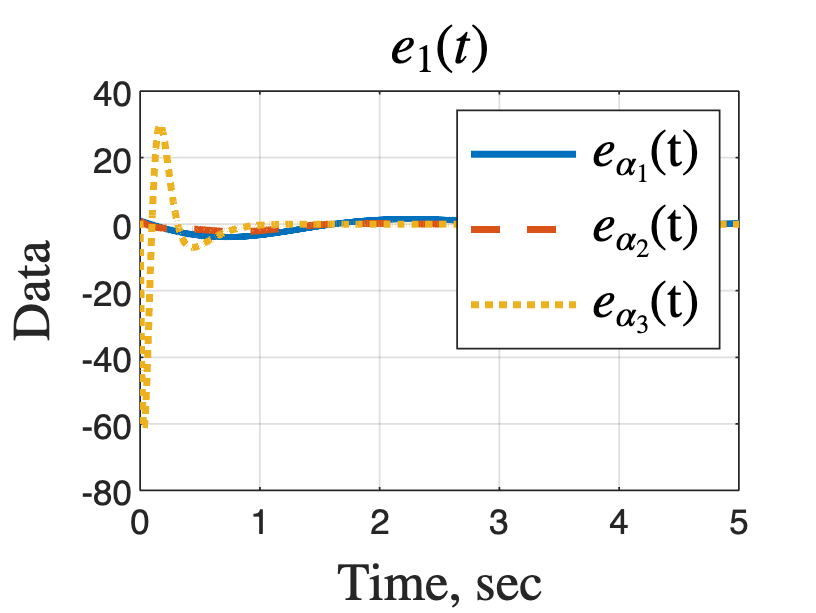

plot(out.e.Time, out.e.Data(:,1), 'LineWidth', 2);
hold on;
plot(out.e1.Time,out.e1.Data(:,1), 'LineWidth', 2, 'LineStyle','--');
hold on;
plot(out.e2.Time,out.e2.Data(:,1), 'LineWidth', 2, 'LineStyle',':');
title('$e_{1}(t)$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$e_{\alpha_{1}}$(t)","$e_{\alpha_{2}}$(t)", "$e_{\alpha_{3}}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;


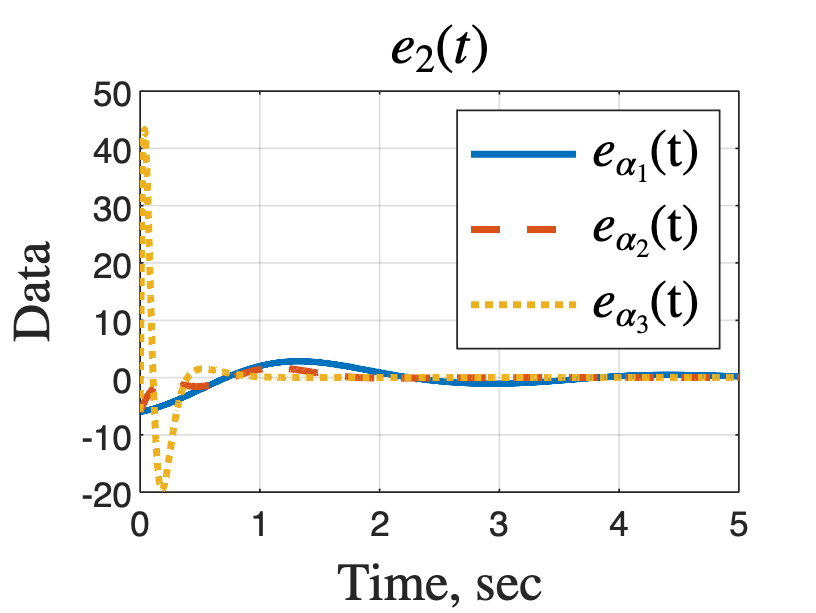

plot(out.e.Time, out.e.Data(:,2), 'LineWidth', 2);
hold on;
plot(out.e1.Time,out.e1.Data(:,2), 'LineWidth', 2, 'LineStyle','--');
hold on;
plot(out.e2.Time,out.e2.Data(:,2), 'LineWidth', 2, 'LineStyle',':');
title('$e_{2}(t)$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$e_{\alpha_{1}}$(t)","$e_{\alpha_{2}}$(t)", "$e_{\alpha_{3}}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;


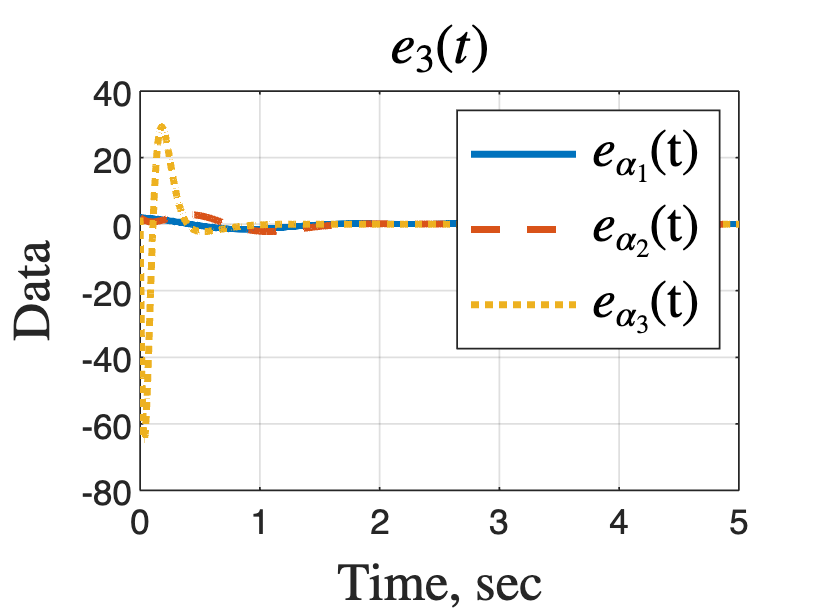

plot(out.e.Time, out.e.Data(:,3), 'LineWidth', 2);
hold on;
plot(out.e1.Time,out.e1.Data(:,3), 'LineWidth', 2, 'LineStyle','--');
hold on;
plot(out.e2.Time,out.e2.Data(:,3), 'LineWidth', 2, 'LineStyle',':');
title('$e_{3}(t)$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$e_{\alpha_{1}}$(t)","$e_{\alpha_{2}}$(t)", "$e_{\alpha_{3}}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;


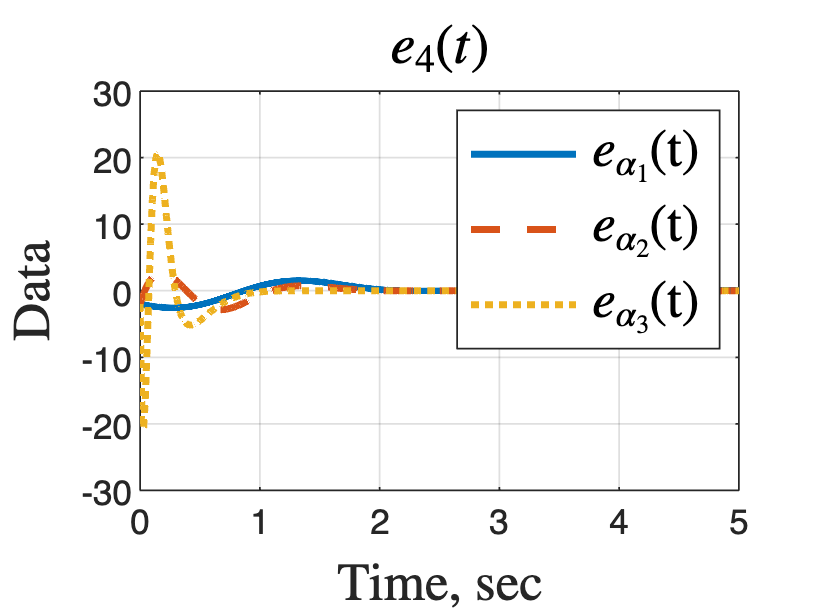

plot(out.e.Time, out.e.Data(:,4), 'LineWidth', 2);
hold on;
plot(out.e1.Time,out.e1.Data(:,4), 'LineWidth', 2, 'LineStyle','--');
hold on;
plot(out.e2.Time,out.e2.Data(:,4), 'LineWidth', 2, 'LineStyle',':');
title('$e_{4}(t)$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$e_{\alpha_{1}}$(t)","$e_{\alpha_{2}}$(t)", "$e_{\alpha_{3}}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;


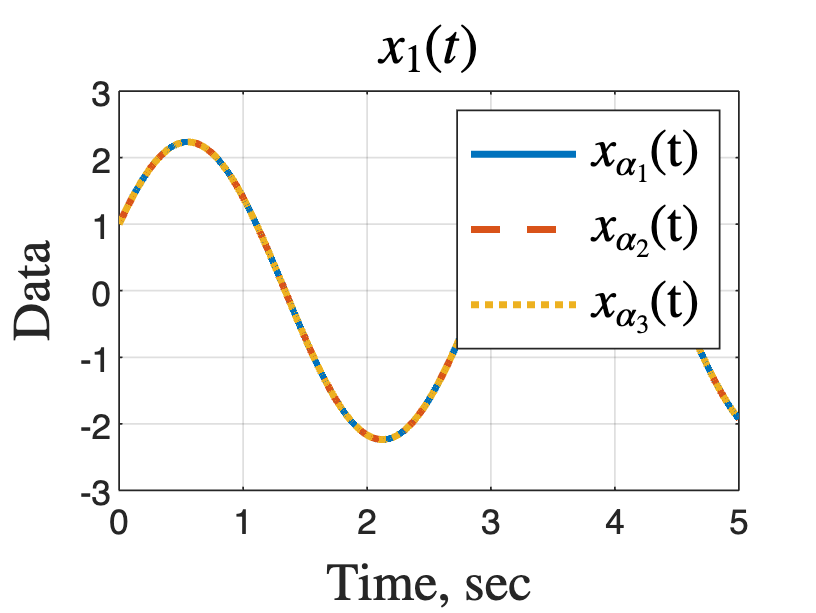

plot(out.x.Time, out.x.Data(:,1), 'LineWidth', 2);
hold on;
plot(out.x1.Time,out.x1.Data(:,1), 'LineWidth', 2, 'LineStyle','--');
hold on;
plot(out.x2.Time,out.x2.Data(:,1), 'LineWidth', 2, 'LineStyle',':');
title('$x_{1}(t)$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$x_{\alpha_{1}}$(t)","$x_{\alpha_{2}}$(t)", "$x_{\alpha_{3}}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;


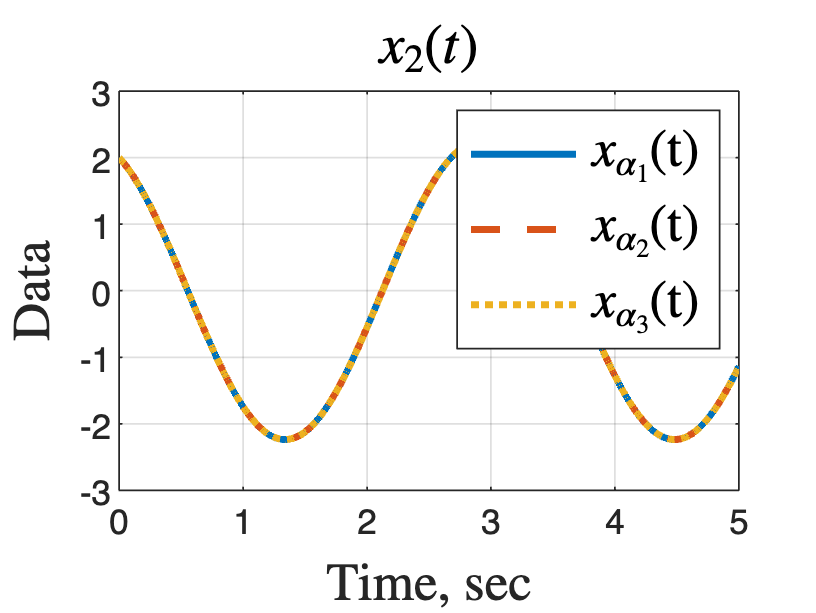

plot(out.x.Time, out.x.Data(:,2), 'LineWidth', 2);
hold on;
plot(out.x1.Time,out.x1.Data(:,2), 'LineWidth', 2, 'LineStyle','--');
hold on;
plot(out.x2.Time,out.x2.Data(:,2), 'LineWidth', 2, 'LineStyle',':');
title('$x_{2}(t)$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$x_{\alpha_{1}}$(t)","$x_{\alpha_{2}}$(t)", "$x_{\alpha_{3}}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;


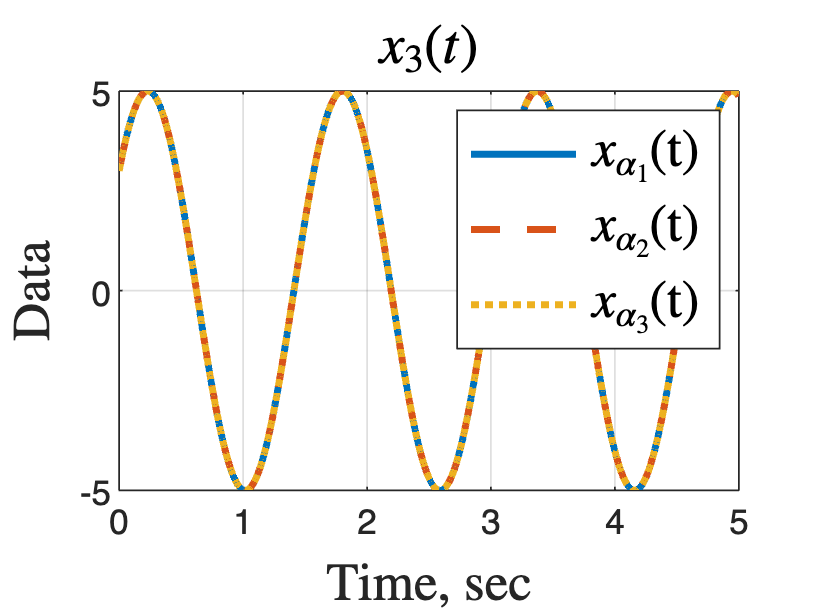

plot(out.x.Time, out.x.Data(:,3), 'LineWidth', 2);
hold on;
plot(out.x1.Time,out.x1.Data(:,3), 'LineWidth', 2, 'LineStyle','--');
hold on;
plot(out.x2.Time,out.x2.Data(:,3), 'LineWidth', 2, 'LineStyle',':');
title('$x_{3}(t)$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$x_{\alpha_{1}}$(t)","$x_{\alpha_{2}}$(t)", "$x_{\alpha_{3}}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;


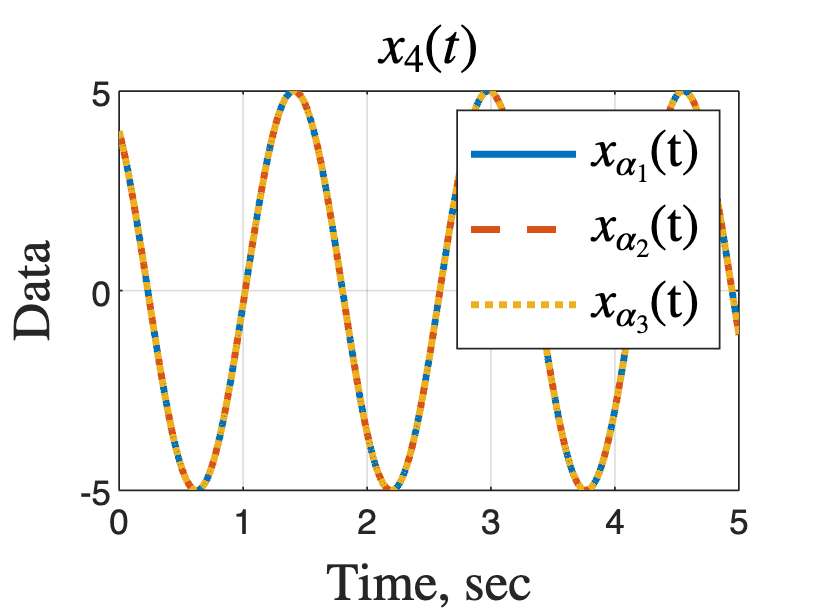

plot(out.x.Time, out.x.Data(:,4), 'LineWidth', 2);
hold on;
plot(out.x1.Time,out.x1.Data(:,4), 'LineWidth', 2, 'LineStyle','--');
hold on;
plot(out.x2.Time,out.x2.Data(:,4), 'LineWidth', 2, 'LineStyle',':');
title('$x_{4}(t)$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$x_{\alpha_{1}}$(t)","$x_{\alpha_{2}}$(t)", "$x_{\alpha_{3}}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;


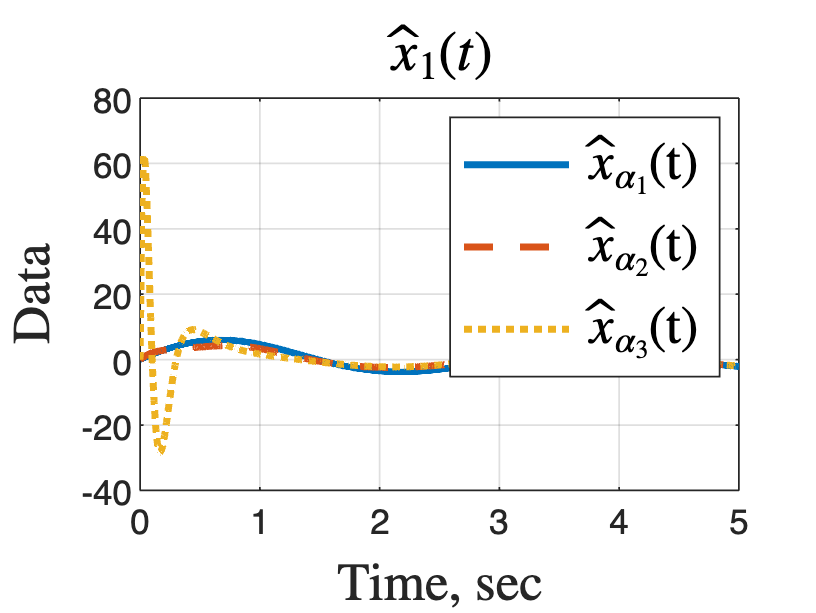

plot(out.xx.Time, out.xx.Data(:,1), 'LineWidth', 2);
hold on;
plot(out.xx1.Time,out.xx1.Data(:,1), 'LineWidth', 2, 'LineStyle','--');
hold on;
plot(out.xx2.Time,out.xx2.Data(:,1), 'LineWidth', 2, 'LineStyle',':');
title('$\hat{x}_{1}(t)$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$\hat{x}_{\alpha_{1}}$(t)","$\hat{x}_{\alpha_{2}}$(t)", "$\hat{x}_{\alpha_{3}}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;


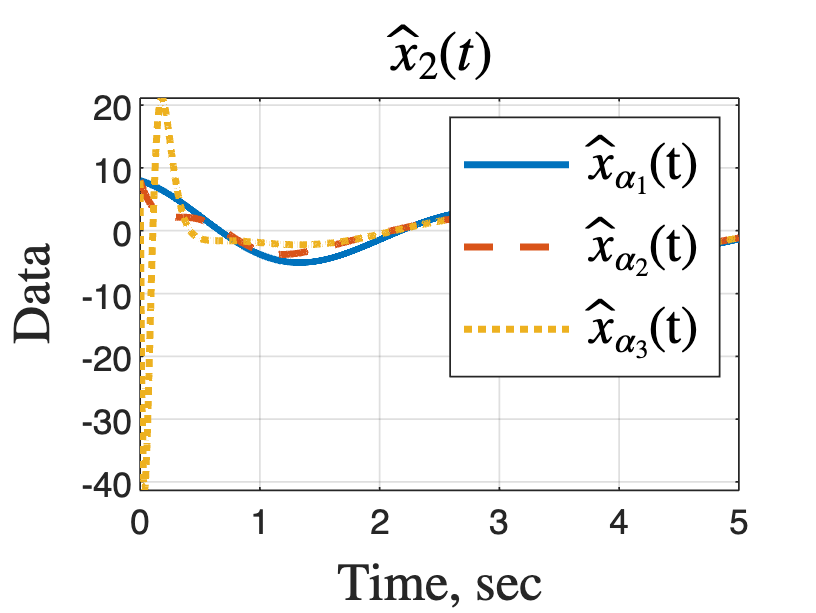

plot(out.xx.Time, out.xx.Data(:,2), 'LineWidth', 2);
hold on;
plot(out.xx1.Time,out.xx1.Data(:,2), 'LineWidth', 2, 'LineStyle','--');
hold on;
plot(out.xx2.Time,out.xx2.Data(:,2), 'LineWidth', 2, 'LineStyle',':');
title('$\hat{x}_{2}(t)$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$\hat{x}_{\alpha_{1}}$(t)","$\hat{x}_{\alpha_{2}}$(t)", "$\hat{x}_{\alpha_{3}}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;


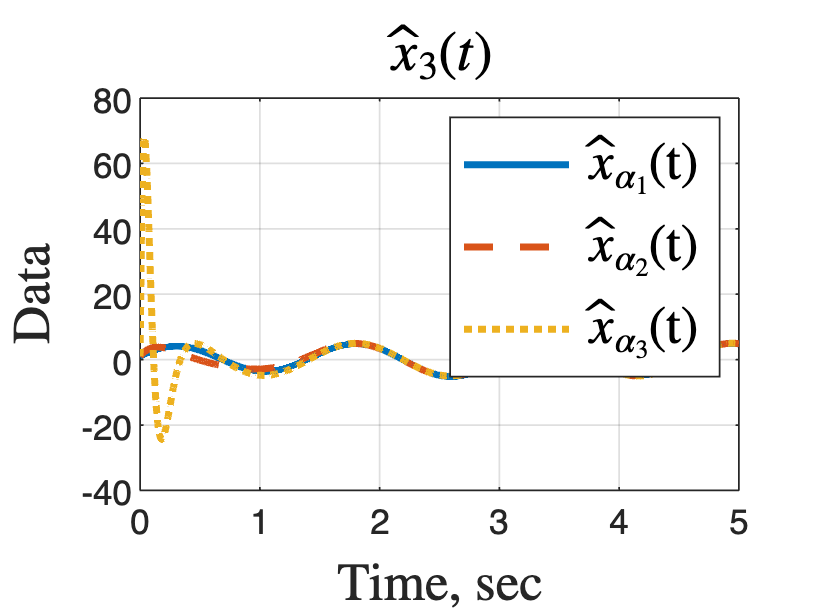

plot(out.xx.Time, out.xx.Data(:,3), 'LineWidth', 2);
hold on;
plot(out.xx1.Time,out.xx1.Data(:,3), 'LineWidth', 2, 'LineStyle','--');
hold on;
plot(out.xx2.Time,out.xx2.Data(:,3), 'LineWidth', 2, 'LineStyle',':');
title('$\hat{x}_{3}(t)$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$\hat{x}_{\alpha_{1}}$(t)","$\hat{x}_{\alpha_{2}}$(t)", "$\hat{x}_{\alpha_{3}}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;


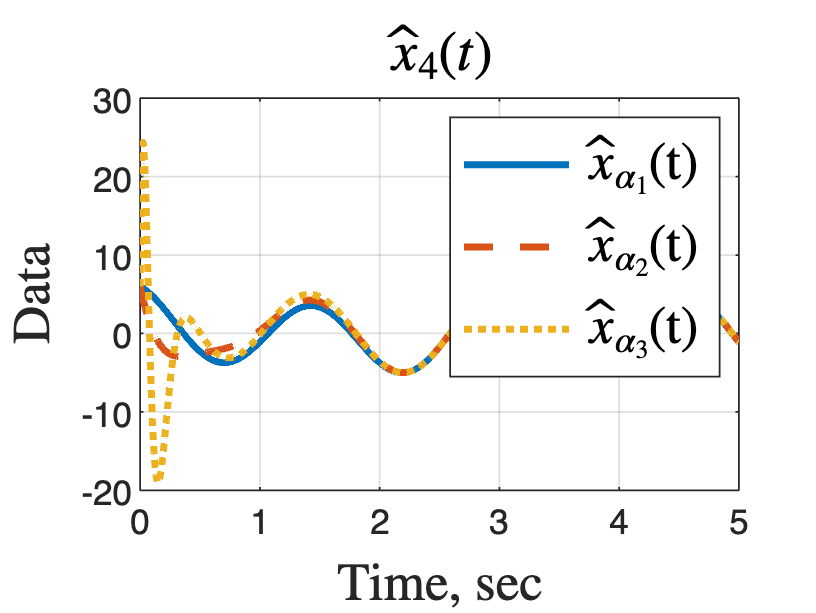

plot(out.xx.Time, out.xx.Data(:,4), 'LineWidth', 2);
hold on;
plot(out.xx1.Time,out.xx1.Data(:,4), 'LineWidth', 2, 'LineStyle','--');
hold on;
plot(out.xx2.Time,out.xx2.Data(:,4), 'LineWidth', 2, 'LineStyle',':');
title('$\hat{x}_{4}(t)$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$\hat{x}_{\alpha_{1}}$(t)","$\hat{x}_{\alpha_{2}}$(t)", "$\hat{x}_{\alpha_{3}}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;


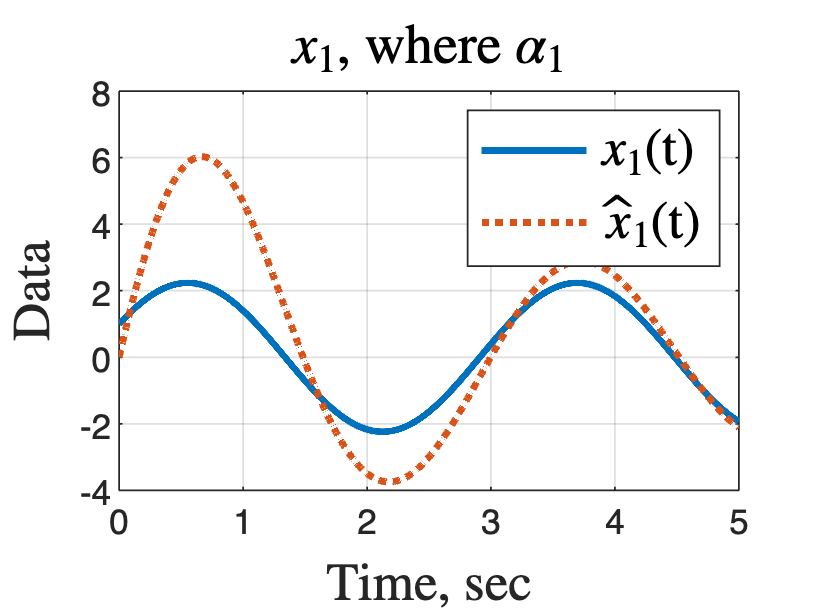

plot(out.x.Time,out.x.Data(:,1), 'LineWidth', 2);
hold on;
plot(out.xx.Time,out.xx.Data(:,1), 'LineWidth', 2, 'LineStyle',':');
title('$x_{1}$, where $\alpha_{1}$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$x_{1}$(t)","$\hat{x}_{1}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;


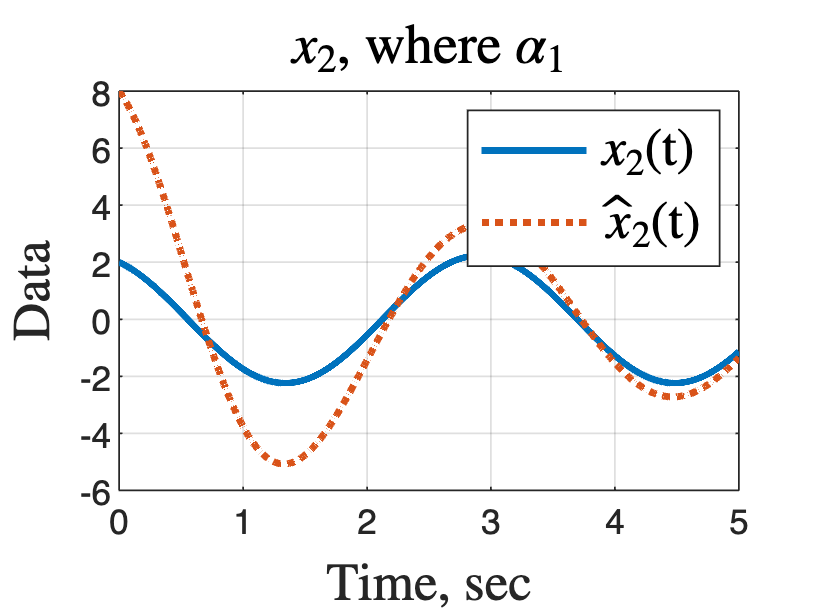

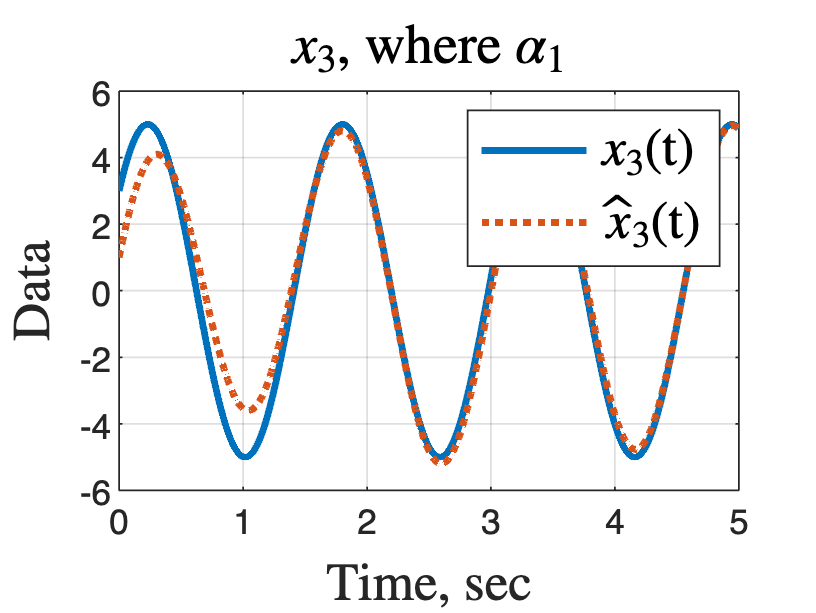

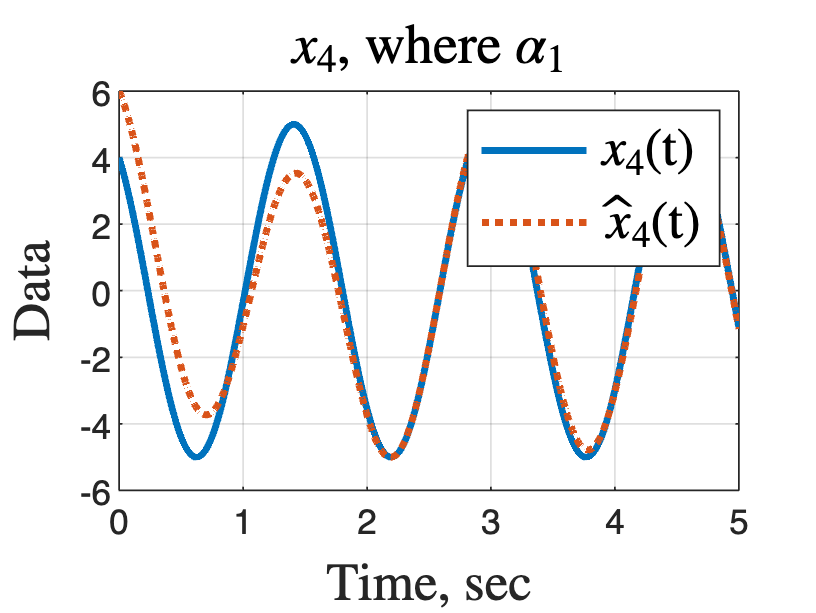

plot(out.x1.Time,out.x1.Data(:,1), 'LineWidth', 2);

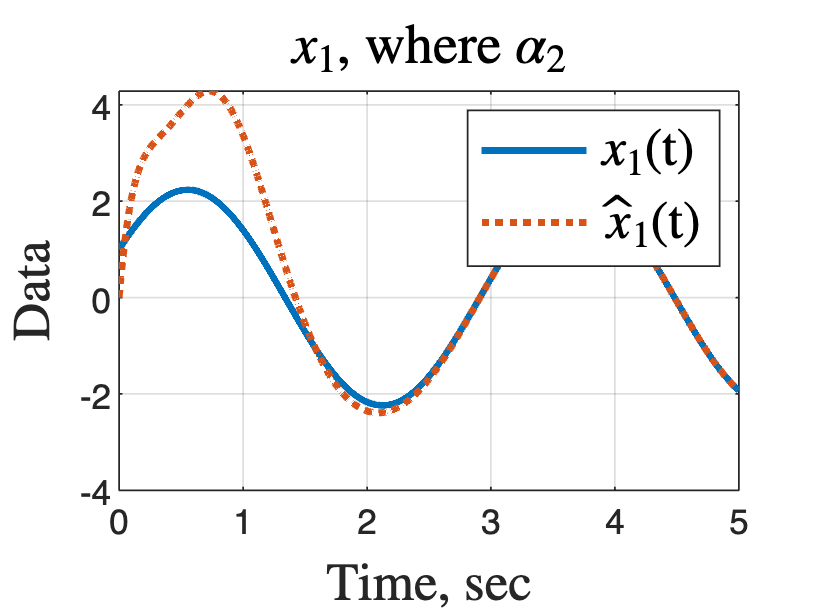

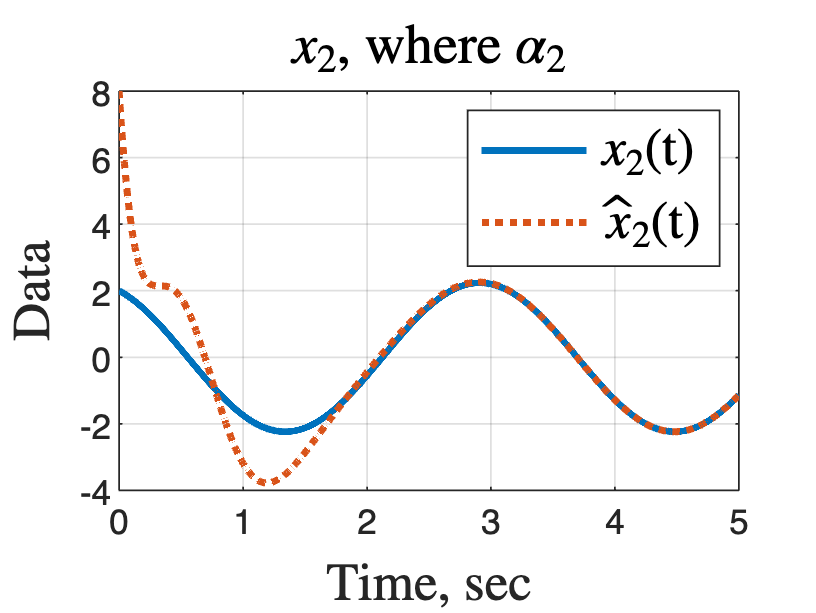

hold on;
plot(out.xx1.Time,out.xx1.Data(:,1), 'LineWidth', 2, 'LineStyle',':');
title('$x_{1}$, where $\alpha_{2}$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$x_{1}$(t)","$\hat{x}_{1}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;


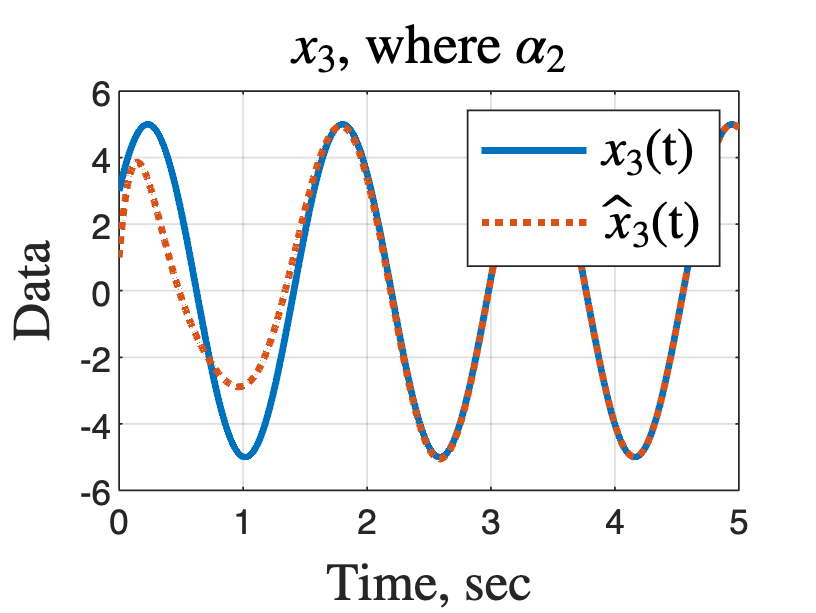

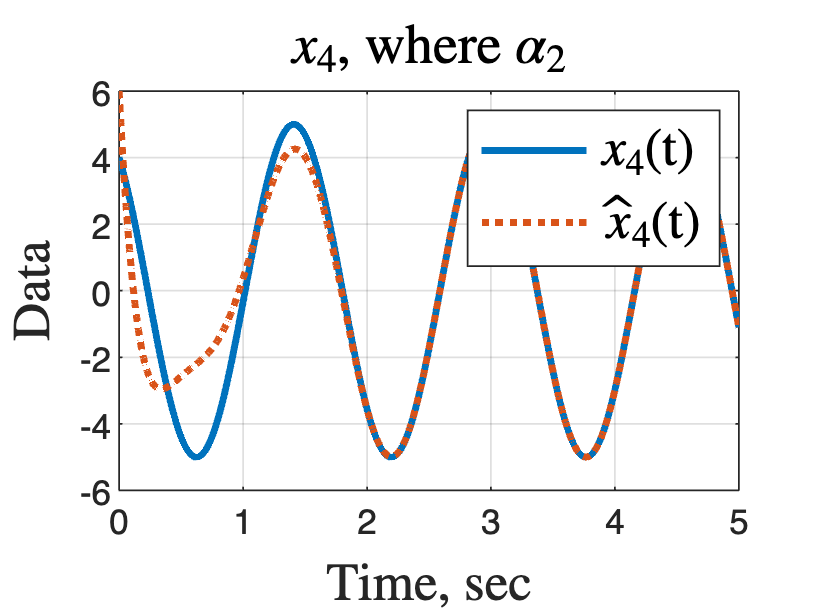

plot(out.x2.Time,out.x2.Data(:,1), 'LineWidth', 2);

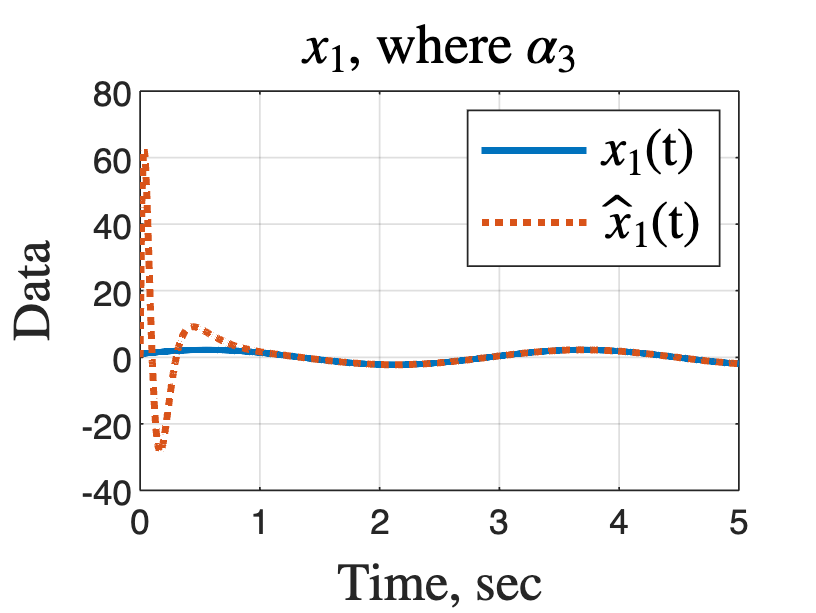

hold on;
plot(out.xx2.Time,out.xx2.Data(:,1), 'LineWidth', 2, 'LineStyle',':');
title('$x_{1}$, where $\alpha_{3}$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$x_{1}$(t)","$\hat{x}_{1}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;


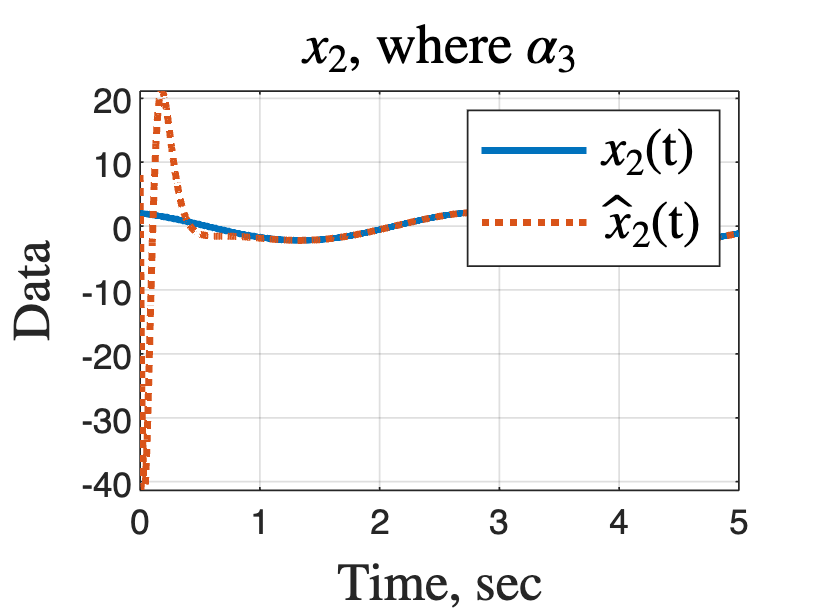

plot(out.x.Time,out.x.Data(:,2), 'LineWidth', 2);
hold on;
plot(out.xx.Time,out.xx.Data(:,2), 'LineWidth', 2, 'LineStyle',':');
title('$x_{2}$, where $\alpha_{1}$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$x_{2}$(t)","$\hat{x}_{2}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

plot(out.x1.Time,out.x1.Data(:,2), 'LineWidth', 2);
hold on;
plot(out.xx1.Time,out.xx1.Data(:,2), 'LineWidth', 2, 'LineStyle',':');
title('$x_{2}$, where $\alpha_{2}$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$x_{2}$(t)","$\hat{x}_{2}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

plot(out.x2.Time,out.x2.Data(:,2), 'LineWidth', 2);
hold on;
plot(out.xx2.Time,out.xx2.Data(:,2), 'LineWidth', 2, 'LineStyle',':');
title('$x_{2}$, where $\alpha_{3}$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$x_{2}$(t)","$\hat{x}_{2}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;


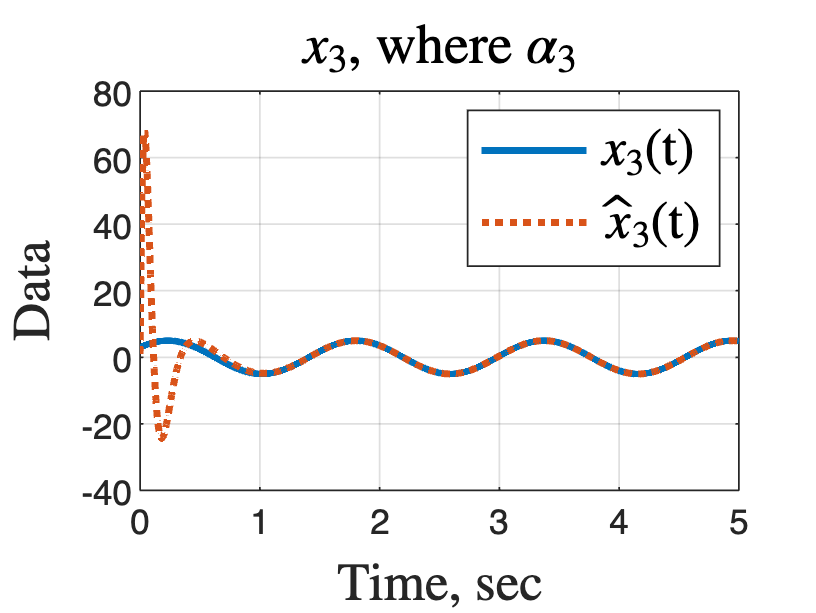

plot(out.x.Time,out.x.Data(:,3), 'LineWidth', 2);
hold on;
plot(out.xx.Time,out.xx.Data(:,3), 'LineWidth', 2, 'LineStyle',':');
title('$x_{3}$, where $\alpha_{1}$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$x_{3}$(t)","$\hat{x}_{3}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

plot(out.x1.Time,out.x1.Data(:,3), 'LineWidth', 2);
hold on;
plot(out.xx1.Time,out.xx1.Data(:,3), 'LineWidth', 2, 'LineStyle',':');
title('$x_{3}$, where $\alpha_{2}$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$x_{3}$(t)","$\hat{x}_{3}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

plot(out.x2.Time,out.x2.Data(:,3), 'LineWidth', 2);
hold on;
plot(out.xx2.Time,out.xx2.Data(:,3), 'LineWidth', 2, 'LineStyle',':');
title('$x_{3}$, where $\alpha_{3}$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$x_{3}$(t)","$\hat{x}_{3}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;


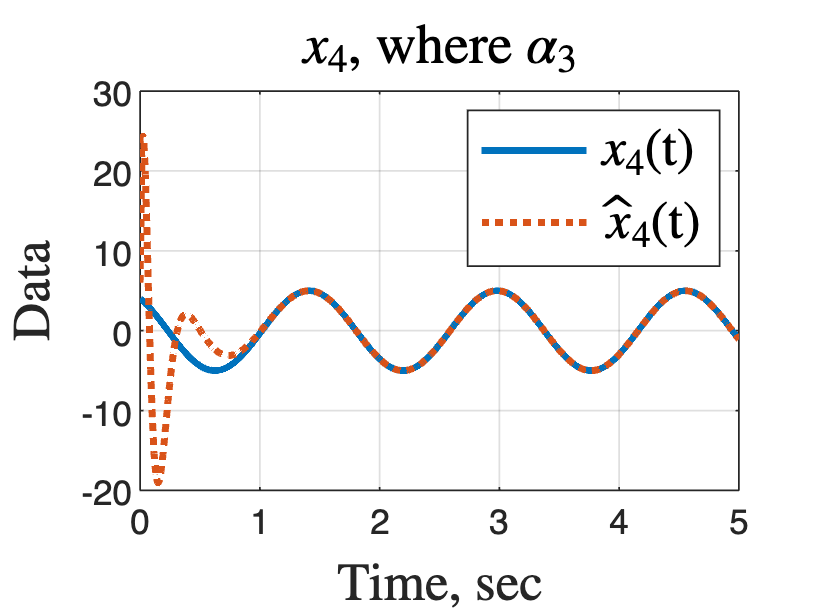

plot(out.x.Time,out.x.Data(:,4), 'LineWidth', 2);
hold on;
plot(out.xx.Time,out.xx.Data(:,4), 'LineWidth', 2, 'LineStyle',':');
title('$x_{4}$, where $\alpha_{1}$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$x_{4}$(t)","$\hat{x}_{4}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

plot(out.x1.Time,out.x1.Data(:,4), 'LineWidth', 2);
hold on;
plot(out.xx1.Time,out.xx1.Data(:,4), 'LineWidth', 2, 'LineStyle',':');
title('$x_{4}$, where $\alpha_{2}$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$x_{4}$(t)","$\hat{x}_{4}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

plot(out.x2.Time,out.x2.Data(:,4), 'LineWidth', 2);
hold on;
plot(out.xx2.Time,out.xx2.Data(:,4), 'LineWidth', 2, 'LineStyle',':');
title('$x_{4}$, where $\alpha_{3}$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$x_{4}$(t)","$\hat{x}_{4}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;